% ============================================================
% TEST_SPLITS
%
% Constitutive verification of:
%
%   1. No split
%   2. Spectral split
%   3. Amor split
%
% Plane-strain 2D formulation.
%
% This script tests several representative strain states and
% verifies:
%
%       psi = psi_plus + psi_minus
%
% for the split formulations.
%
% ============================================================

clear;
clc;

%% =========================================================
% MATERIAL
% ==========================================================

material.E  = 210000;
material.nu = 0.30;

model.dim = 2;


%% =========================================================
% STRAIN MAGNITUDE
% ==========================================================

eps0 = 1e-3;


%% =========================================================
% DEFINE TEST STRAIN STATES
%
% Engineering strain notation:
%
%   [exx
%    eyy
%    gxy]
%
% where
%
%   gxy = 2*exy
%
% ==========================================================

strainNames = {
    'Pure x tension'
    'Pure x compression'
    'Pure y tension'
    'Pure y compression'
    'Equibiaxial tension'
    'Equibiaxial compression'
    'Pure shear'
    'Mixed tension/compression'
    'Rotated tension'
    'Rotated compression'
    };


strain = zeros(10,3);

% ----------------------------------------------------------
% 1. Pure x tension
% ----------------------------------------------------------

strain(1,:) = [
    eps0, ...
    0, ...
    0
    ];


% ----------------------------------------------------------
% 2. Pure x compression
% ----------------------------------------------------------

strain(2,:) = [
    -eps0, ...
    0, ...
    0
    ];


% ----------------------------------------------------------
% 3. Pure y tension
% ----------------------------------------------------------

strain(3,:) = [
    0, ...
    eps0, ...
    0
    ];


% ----------------------------------------------------------
% 4. Pure y compression
% ----------------------------------------------------------

strain(4,:) = [
    0, ...
    -eps0, ...
    0
    ];


% ----------------------------------------------------------
% 5. Equibiaxial tension
% ----------------------------------------------------------

strain(5,:) = [
    eps0, ...
    eps0, ...
    0
    ];


% ----------------------------------------------------------
% 6. Equibiaxial compression
% ----------------------------------------------------------

strain(6,:) = [
    -eps0, ...
    -eps0, ...
    0
    ];


% ----------------------------------------------------------
% 7. Pure shear
% ----------------------------------------------------------

strain(7,:) = [
    0, ...
    0, ...
    eps0
    ];


% ----------------------------------------------------------
% 8. Mixed tension/compression
% ----------------------------------------------------------

strain(8,:) = [
    eps0, ...
    -0.5*eps0, ...
    0
    ];


% ----------------------------------------------------------
% 9. Rotated tensile state
% ----------------------------------------------------------
%
% Start with principal strains:
%
%   eps1 = eps0
%   eps2 = 0
%
% Rotate by 45 degrees.
%
% ==========================================================

theta = 45*pi/180;

R = [
    cos(theta), -sin(theta);
    sin(theta),  cos(theta)
    ];

Eprincipal = [
    eps0, 0;
    0,    0
    ];

Erot = R*Eprincipal*R';

strain(9,:) = [
    Erot(1,1), ...
    Erot(2,2), ...
    2*Erot(1,2)
    ];


% ----------------------------------------------------------
% 10. Rotated compression
% ----------------------------------------------------------

Eprincipal = [
    -eps0, 0;
    0,     0
    ];

Erot = R*Eprincipal*R';

strain(10,:) = [
    Erot(1,1), ...
    Erot(2,2), ...
    2*Erot(1,2)
    ];


%% =========================================================
% SPLIT TYPES
% ==========================================================

splitNames = {
    'none'
    'amor'
    'spectral'
    };

nSplit = numel(splitNames);
nTest  = size(strain,1);


%% =========================================================
% STORAGE
% ==========================================================

psi      = zeros(nTest,nSplit);
psiPlus  = zeros(nTest,nSplit);
psiMinus = zeros(nTest,nSplit);

energyError = zeros(nTest,nSplit);


%% =========================================================
% RUN TESTS
% ==========================================================

for s = 1:nSplit

    model.split = splitNames{s};

    for i = 1:nTest

        epsVoigt = strain(i,:).';

        split = computeSplitInfo( ...
            epsVoigt, ...
            material, ...
            model);

        psi(i,s)      = split.psi;
        psiPlus(i,s)  = split.psiPlus;
        psiMinus(i,s) = split.psiMinus;

        % Energy decomposition error
        energyError(i,s) = ...
            split.psi - ...
            (split.psiPlus + split.psiMinus);

    end

end


%% =========================================================
% PRINT RESULTS
% ==========================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf(' CONSTITUTIVE SPLIT VERIFICATION\n');

 CONSTITUTIVE SPLIT VERIFICATION


fprintf('============================================================\n');


for s = 1:nSplit

    fprintf('\n');
    fprintf('------------------------------------------------------------\n');
    fprintf('Split: %s\n',upper(splitNames{s}));
    fprintf('------------------------------------------------------------\n');

    fprintf( ...
        '%-30s %14s %14s %14s %14s\n', ...
        'Strain state', ...
        'psi', ...
        'psi+', ...
        'psi-', ...
        'error');

    for i = 1:nTest

        fprintf( ...
            '%-30s %14.6e %14.6e %14.6e %14.6e\n', ...
            strainNames{i}, ...
            psi(i,s), ...
            psiPlus(i,s), ...
            psiMinus(i,s), ...
            energyError(i,s));

    end

end

------------------------------------------------------------


Split: NONE


------------------------------------------------------------


Strain state                              psi           psi+           psi-          error


Pure x tension                   1.413462e-01   1.413462e-01   0.000000e+00   0.000000e+00
Pure x compression               1.413462e-01   1.413462e-01   0.000000e+00   0.000000e+00
Pure y tension                   1.413462e-01   1.413462e-01   0.000000e+00   0.000000e+00
Pure y compression               1.413462e-01   1.413462e-01   0.000000e+00   0.000000e+00
Equibiaxial tension              4.038462e-01   4.038462e-01   0.000000e+00   0.000000e+00
Equibiaxial compression          4.038462e-01   4.038462e-01   0.000000e+00   0.000000e+00
Pure shear                       4.038462e-02   4.038462e-02   0.000000e+00   0.000000e+00
Mixed tension/compression        1.161058e-01   1.161058e-01   0.000000e+00   0.000000e+00
Rotated tension                  1.413462e-01   1.413462e-01   0.000000e+00   0.000000e+00
Rotated compression              1.413462e-01   1.413462e-01   0.000000e+00   0.000000e+00


------------------------------------------------------------


Split: AMOR


------------------------------------------------------------


Strain state                              psi           psi+           psi-          error


Pure x tension                   1.413462e-01   1.413462e-01   0.000000e+00   0.000000e+00
Pure x compression               1.413462e-01   5.384615e-02   8.750000e-02   0.000000e+00
Pure y tension                   1.413462e-01   1.413462e-01   0.000000e+00   0.000000e+00
Pure y compression               1.413462e-01   5.384615e-02   8.750000e-02   0.000000e+00
Equibiaxial tension              4.038462e-01   4.038462e-01   0.000000e+00   0.000000e+00
Equibiaxial compression          4.038462e-01   5.384615e-02   3.500000e-01   0.000000e+00
Pure shear                       4.038462e-02   4.038462e-02   2.187500e-20   0.000000e+00
Mixed tension/compression        1.161058e-01   1.161058e-01   0.000000e+00  -1.387779e-17
Rotated tension                  1.413462e-01   1.413462e-01   0.000000e+00   0.000000e+00
Rotated compression              1.413462e-01   5.384615e-02   8.750000e-02   0.000000e+00


------------------------------------------------------------


Split: SPECTRAL


------------------------------------------------------------


Strain state                              psi           psi+           psi-          error


Pure x tension                   1.413462e-01   1.413462e-01   4.038462e-20   0.000000e+00
Pure x compression               1.413462e-01   4.038462e-20   1.413462e-01   0.000000e+00
Pure y tension                   1.413462e-01   1.413462e-01   4.038462e-20   0.000000e+00
Pure y compression               1.413462e-01   4.038462e-20   1.413462e-01   0.000000e+00
Equibiaxial tension              4.038462e-01   4.038462e-01   2.019231e-20   0.000000e+00
Equibiaxial compression          4.038462e-01   2.019231e-20   4.038462e-01   0.000000e+00
Pure shear                       4.038462e-02   2.019231e-02   2.019231e-02   1.387779e-17
Mixed tension/compression        1.161058e-01   9.591346e-02   2.019231e-02   0.000000e+00
Rotated tension                  1.413462e-01   1.413462e-01   4.038462e-20   0.000000e+00
Rotated compression              1.413462e-01   4.038462e-20   1.413462e-01   0.000000e+00




%% =========================================================
% ENERGY CONSISTENCY CHECK
% ==========================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf(' ENERGY DECOMPOSITION CHECK\n');

 ENERGY DECOMPOSITION CHECK


fprintf('============================================================\n');


for s = 1:nSplit

    maxError = max(abs(energyError(:,s)));

    maxRelativeError = max( ...
        abs(energyError(:,s)) ./ ...
        max(abs(psi(:,s)),eps));

    fprintf( ...
        '%-12s : max abs error = %.6e, ', ...
        splitNames{s}, ...
        maxError);

    fprintf( ...
        'max relative error = %.6e\n', ...
        maxRelativeError);

end

none         : max abs error = 0.000000e+00, 

max relative error = 0.000000e+00


amor         : max abs error = 1.387779e-17, 

max relative error = 1.195271e-16


spectral     : max abs error = 1.387779e-17, 

max relative error = 3.436405e-16




%% =========================================================
% CHECK NON-NEGATIVITY
% ==========================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf(' NON-NEGATIVITY CHECK\n');

 NON-NEGATIVITY CHECK


fprintf('============================================================\n');


for s = 1:nSplit

    minPsiPlus = min(psiPlus(:,s));
    minPsiMinus = min(psiMinus(:,s));

    fprintf( ...
        '%-12s : min(psi+) = %+12.5e, ', ...
        splitNames{s}, ...
        minPsiPlus);

    fprintf( ...
        'min(psi-) = %+12.5e\n', ...
        minPsiMinus);

end

none         : min(psi+) = +4.03846e-02, 

min(psi-) = +0.00000e+00


amor         : min(psi+) = +4.03846e-02, 

min(psi-) = +0.00000e+00


spectral     : min(psi+) = +2.01923e-20, 

min(psi-) = +2.01923e-20




%% =========================================================
% CHECK NONE-SPLIT
% ==========================================================
%
% For no split:
%
%       psi+ = psi
%       psi- = 0
%
% ==========================================================

noneID = strcmpi(splitNames,'none');

noneErrorPlus = ...
    max(abs(psiPlus(:,noneID) - psi(:,noneID)));

noneErrorMinus = ...
    max(abs(psiMinus(:,noneID)));

fprintf('\n');
fprintf('============================================================\n');

fprintf(' NO-SPLIT CHECK\n');

 NO-SPLIT CHECK


fprintf('============================================================\n');


fprintf('max |psi+ - psi| = %.6e\n',noneErrorPlus);

max |psi+ - psi| = 0.000000e+00


fprintf('max |psi-|        = %.6e\n',noneErrorMinus);

max |psi-|        = 0.000000e+00


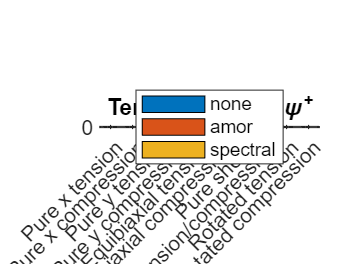



%% =========================================================
% PLOT psi+ FOR EACH SPLIT
% ==========================================================

figure('Color','w');

bar(psiPlus);

xlabel('Strain test case');
ylabel('\psi^+');

title('Tensile energy \psi^+');

set(gca, ...
    'XTick',1:nTest, ...
    'XTickLabel',strainNames, ...
    'XTickLabelRotation',45, ...
    'FontSize',10);

legend(splitNames,'Location','best');

grid on;

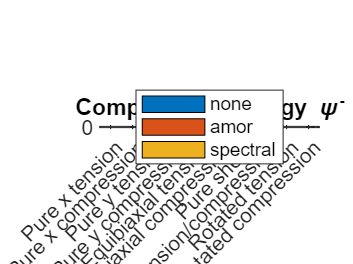



%% =========================================================
% PLOT psi-
% ==========================================================

figure('Color','w');

bar(psiMinus);

xlabel('Strain test case');
ylabel('\psi^-');

title('Compressive energy \psi^-');

set(gca, ...
    'XTick',1:nTest, ...
    'XTickLabel',strainNames, ...
    'XTickLabelRotation',45, ...
    'FontSize',10);

legend(splitNames,'Location','best');

grid on;



%% =========================================================
% FINAL AUTOMATIC VERDICT
% ==========================================================

tol = 1e-10;

allPassed = true;

for s = 1:nSplit

    if max(abs(energyError(:,s))) > tol

        fprintf('\nWARNING: Energy decomposition failed for %s.\n', ...
            splitNames{s});

        allPassed = false;

    end

    if min(psiPlus(:,s)) < -tol

        fprintf('\nWARNING: Negative psi+ detected for %s.\n', ...
            splitNames{s});

        allPassed = false;

    end

    if min(psiMinus(:,s)) < -tol

        fprintf('\nWARNING: Negative psi- detected for %s.\n', ...
            splitNames{s});

        allPassed = false;

    end

end

if allPassed

    fprintf('\n');
    fprintf('============================================================\n');
    fprintf(' ALL BASIC SPLIT TESTS PASSED\n');
    fprintf('============================================================\n');

else

    fprintf('\n');
    fprintf('============================================================\n');
    fprintf(' SOME SPLIT TESTS FAILED -- INSPECT RESULTS\n');
    fprintf('============================================================\n');

end

 ALL BASIC SPLIT TESTS PASSED
